video = VideoReader('background.avi');
frames = video.NumFrames;
watermark = imread('1.jpg');
watermark = rgb2gray(watermark);
vid_height = video.Height;
vid_width = video.Width;

% Resize the watermark 
watermark = imresize(watermark, [vid_height vid_width]);

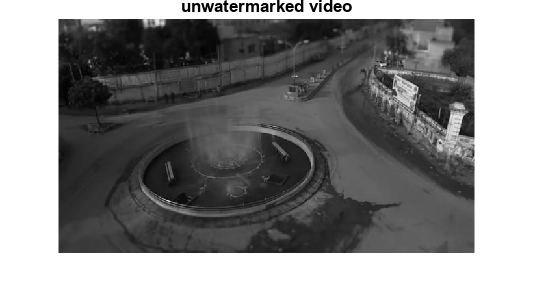

watermarkedVideo = VideoWriter('watermarked_video.avi');
open(watermarkedVideo);

% Loop through each frame of the video
for i =  1:frames
    frame = read(video, i);
    frame = rgb2gray(frame);
    % Apply SVD to the frame
    [U, S, V] = svd(double(frame));
    [U_W, S_W, V_W] = svd(double(watermark));
    
    % Embed the watermark into the singular values
    alpha = 0.5; % strength parameter
    S_watermarked = S + alpha * S_W;
    % Reconstruct the watermarked frame
    frame_watermarked = U * S_watermarked * V';
    % Write the watermarked frame to the video file
    writeVideo(watermarkedVideo, rescale(frame_watermarked));
end

close(watermarkedVideo);
w_video = VideoReader('watermarked_video.avi');
frames = w_video.NumFrames;

i=100;
frame = read(video, i);
frame_2 = read(w_video, i);
imshow(frame); title('unwatermarked video')

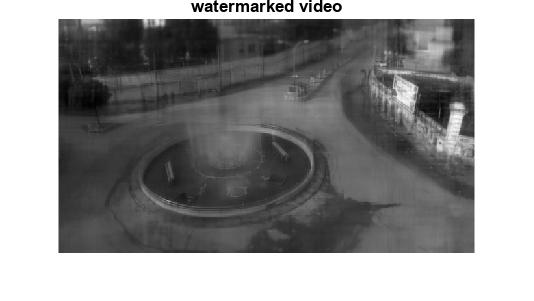

imshow(frame_2); title('watermarked video')

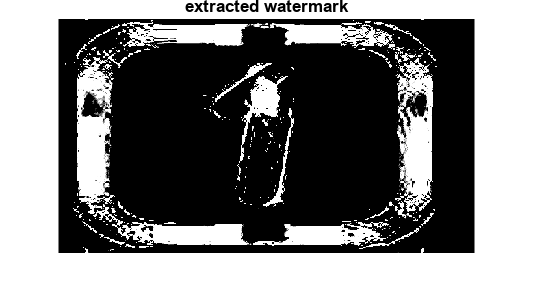

frame = rgb2gray(frame);
frame_2 = rgb2gray(frame_2);
[U, S, V] = svd(double(frame));
[U1, S1, V1] = svd(double(frame_2));
ss1 = (S - S1)/alpha;

% Reconstruct the watermarked frame
extracted_watermark = U_W * ss1 * V_W';
imshow((extracted_watermark));
title('extracted watermark')

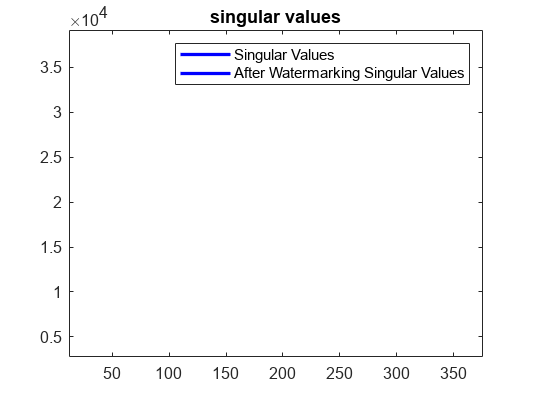

%singular value comparison
[~, Sact, ~] = svd(double(frame));
[~, Smod, ~] = svd(double(frame_2));

figure;
plot(Sact, 'b', 'LineWidth', 2);
hold on;
plot(Smod, 'r--', 'LineWidth', 2);
legend('Singular Values','After Watermarking Singular Values');
hold off;

title("singular values")

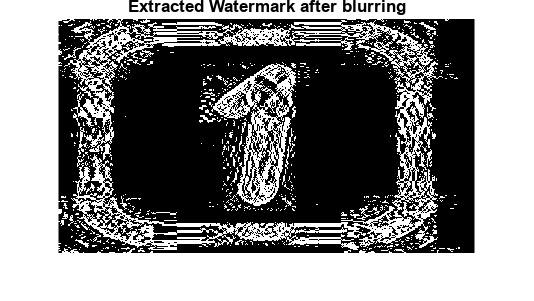

% Initialize the blurred watermarked video
blurredWatermarkedVideo = VideoWriter('blured-background-watermarked.avi');
open(blurredWatermarkedVideo);

% Define the blur filter
blurFilter = fspecial('gaussian', [5 5], 2); % Gaussian blur filter with a kernel size of 5x5 

% Loop through each frame of the watermarked video
for i = 1:frames
    frame = read(w_video, i);
    
    % Apply the blur filter to the frame
    blurredFrame = imfilter(frame, blurFilter);
    
    % Write the blurred frame to the video file
    writeVideo(blurredWatermarkedVideo, blurredFrame);
end

close(blurredWatermarkedVideo);

% Re-open the blurred watermarked video for watermark extraction
blurredVideo = VideoReader('blured-background-watermarked.avi');
frames = blurredVideo.NumFrames;

% Initialize the extracted watermark matrix
extractedWatermarkMatrix = zeros(vid_height, vid_width);

% Loop through each frame of the blurred watermarked video
for i = 1:frames
    frame = read(blurredVideo, i);
    frame = rgb2gray(frame);
    
    % Apply SVD to the frame
    [U, S, V] = svd(double(frame));
    
    % Extract the singular values difference
    ss_diff = (S - S1) / alpha;
    
    % Reconstruct the extracted watermark
    extractedWatermark = U_W * ss_diff * V_W';
    
    % Add the extracted watermark to the accumulated matrix
    extractedWatermarkMatrix = extractedWatermarkMatrix + extractedWatermark;
end

% Display the extracted watermark
imshow(extractedWatermarkMatrix);
title('Extracted Watermark after blurring');


% Save the extracted watermark as an image
imwrite(extractedWatermarkMatrix, 'extracted_watermark_blur.png');
